## MATLAB大作业

clear; clc;
format long

## 第一部分：数据导入与可视化

Example: 利用StatisticsAnalysis对象，一步完成（1）导入参数的检测、修改；（2）数据的导入；（3）表格的检索；（4）一般统计指标的计算.

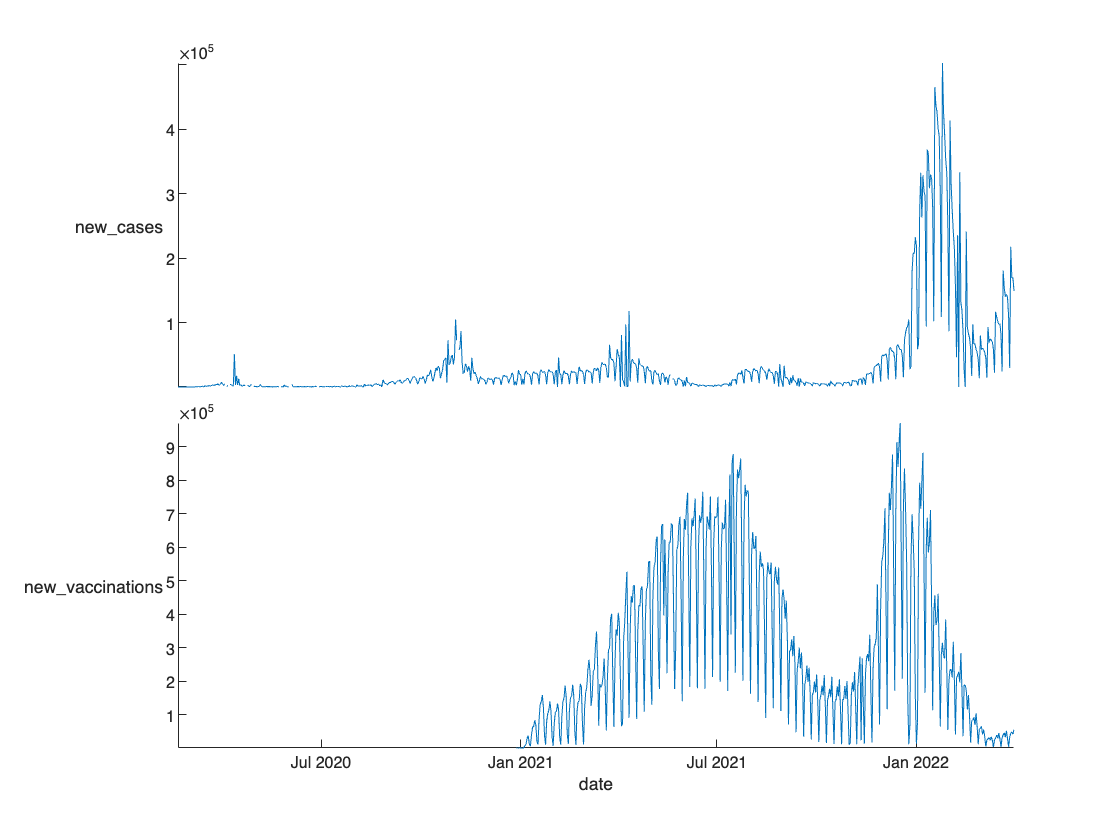

% path_users = './data/Foursquare/users.csv';
% path_tips = './data/Foursquare/tips.csv';
% path_friends = './data/Foursquare/friends.csv';
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';
SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}, ...
        'SelectedVariableNames', {'date', 'new_cases', 'new_vaccinations'}, ...
        'DataLines', [4850, Inf] ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France', ... Country
        'date', arange(["2020-01-01", "2022-04-01"], 'closed') ... Time Range
        }, ...
     'TagsGenerateOptions', { ...
        'CustomTagName', {'increment', [0 1 1], 'continuous', [0 1 1]}, ...
        'CustomTagFunction', { ...
            'increment', 'SummationOfIncrements', @(x,y)tsnansum(x{:,:}) ...
            } ...
        }...
    );
daily = SA.TimeTable;
% figure(1); plot(daily, 'new_cases'); datetick x;
figure(1); stackedplot(daily);

daily.Properties

ans =   TimetableProperties with properties:
               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [772×1 datetime]
                 StartTime: 2020-02-20
                SampleRate: NaN
                  TimeStep: 1d
   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [772 3]
                  TagNames: {{2×1 cell}  {2×1 cell}}
               UniqueCount: {[746]  [460]}
                ValueClass: {'double'  'double'}
              MissingCount: {[10]  [312]}
              MissingRatio: {[0.0129

## 第二部分：缺失值处理

Example: 利用tableMissingValuesHelper函数，补全缺失值. 例如，在上面的表格daily中，两列增量都各自有所缺少.

% 先检测缺失值的位置，确定其特征，再选用对应的补全方法
[~, missingList] = tableMissingValuesHelper(daily)

missingList = struct with fields:
           new_cases: {[45 45]  [48 48]  [64 64]  [70 70]  [95 95]  [104 105]  [130 130]  [259 259]  [456 456]}
    new_vaccinations: {[1 312]}

% 上面的数据说明，new_cases缺失的数据较分散，而new_vaccinations缺失的数据只分布在起始的一段时间
SA = SA.UpdateImportOptions({'SelectedVariableNames', {'total_cases', 'total_vaccinations'}}, 'append').TableImportAndSelection;
data2 = tableMissingValuesHelper(SA.TimeTable, 'VariableNames', {'new_cases', 'total_cases'}, 'Style', 'Increment-Addition', 'InterpolationStyle', 'LinearRound');
data2 = tableMissingValuesHelper(data2, 'VariableNames', {'new_vaccinations', 'total_vaccinations'}, 'Style', 'Increment-Addition', 'InterpolationStyle', 'LinearRound', 'ConstantValues', 0);

tp = SA.TimeTable(:,3);
tp = renamevars(tp, 'total_cases', 'total_cases_1');

tp = 772×1 timetable
       date       total_cases_1
    __________    _____________
    2020-02-20          12     
    2020-02-21          12     
    2020-02-22          12     
    2020-02-23          12     
    2020-02-24          12     
    2020-02-25          14     
    2020-02-26          18     
    2020-02-27          38     
    2020-02-28          57     
    2020-02-29         100     
    2020-03-01         130     
    2020-03-02         191     
    2020-03-03         212     
    2020-03-04         288     
    2020-03-05         426     
    2020-03-06         616     

dailyTC = [data2(:,3), tp]

dailyTC = 772×2 timetable
       date       total_cases    total_cases_1
    __________    ___________    _____________
    2020-02-20         12              12     
    2020-02-21         12              12     
    2020-02-22         12              12     
    2020-02-23         12              12     
    2020-02-24         12              12     
    2020-02-25         14              14     
    2020-02-26         18              18     
    2020-02-27         38              38     
    2020-02-28         57              57     
    2020-02-29        100             100     
    2020-03-01        130             130     
    2020-03-02        191             191     
    

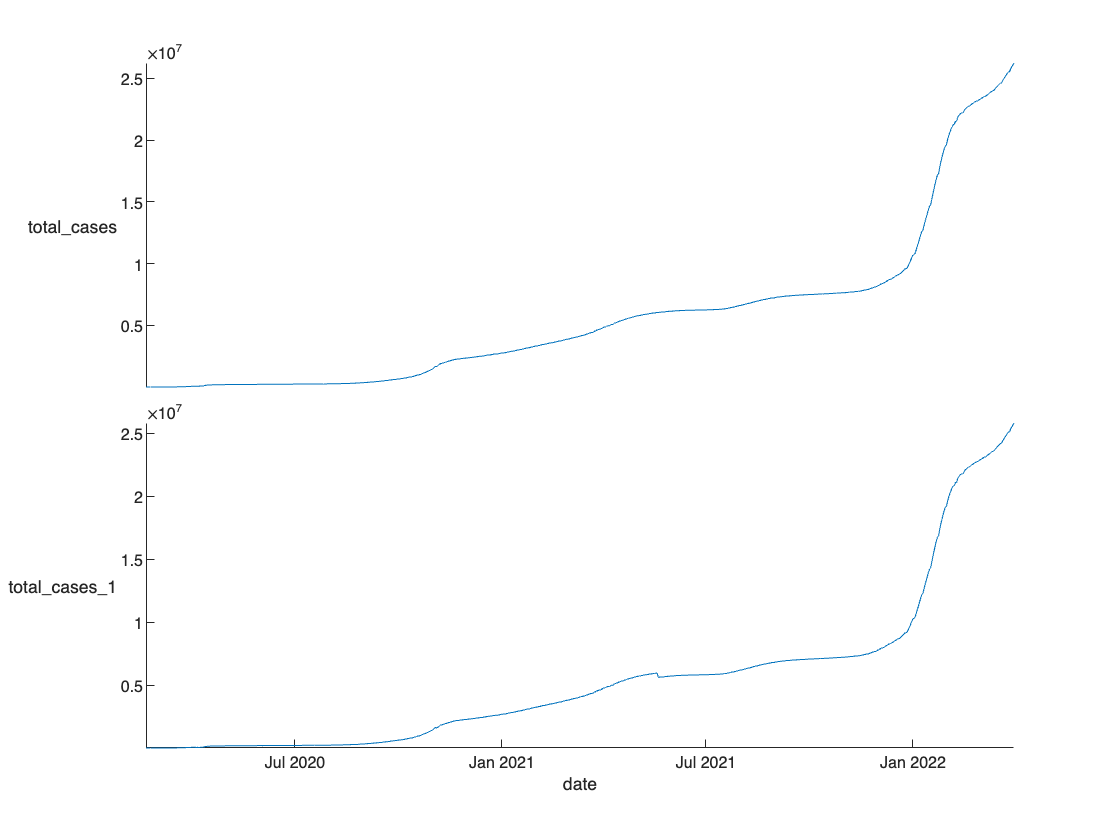

figure(2); stackedplot(dailyTC);

daily2 = daily;
Smooth = @(x)smooth(x, 10);
daily2{:,1} = Smooth(daily2{:,1}); daily2{:,2} = Smooth(daily2{:,2})

daily2 = 772×2 timetable
       date           new_cases         new_vaccinations 
    __________    __________________    _________________
    2020-02-20     -1.66523660253347    -5539.79857912833
    2020-02-21    -0.763435297794968     -5522.0387573886
    2020-02-22     0.306060276388921    -5504.27877174893
    2020-02-23      1.55608755507806    -5486.51862065142
    2020-02-24      2.95032206507285    -5468.75830252223
    2020-02-25      6.29826493937481    -5450.99781576511
    2020-02-26      11.2745605077683    -5433.23715876146
    2020-02-27       17.430567546543    -5415.47632987487
    2020-02-28      24.3892240763598    -5397.71532744659
    2020-02-29      30.8133395306629    -5379.95414979448
    

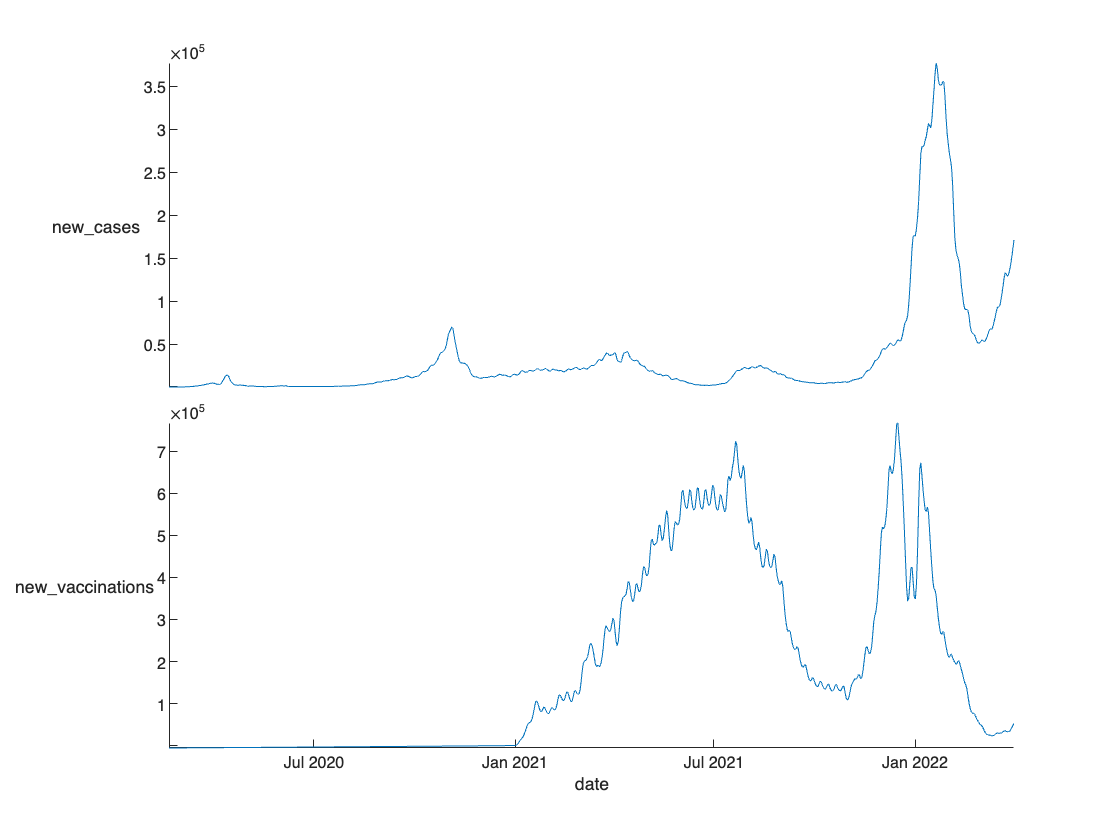


figure(2); stackedplot(daily2);

SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', { ...
            'new_vaccinations', 'double';
            'total_vaccinations', 'double' ...
            }; ...
        'SelectedVariableNames', {'date', 'new_cases', 'total_cases'} ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France'; ... Country
        'date', { ...
            arange(["2020-01-01", "2020-12-31"], 'closed')
            } ... Time Range
        } ... % Will Automatically Select Table Before Importing Table
    ).TagsGenerate('QuickStyle', {'MissingMap'});
data = SA.Table;

% 缺失值处理
% [~, list1] = tableMissingValuesHelper(data, ...
%     'VariableNames', {'new_cases', 'total_cases'}, ...
%     'Style', 'Interpolation' ...
%     );
[dataN, list2] = tableMissingValuesHelper(data, ...
    'VariableNames', {'new_cases', 'total_cases'}, ...
    'Style', 'Increment-Addition' ...
    );
% dataN = StatisticsAnalysis( ...
%     'Table', dataN, ...
%     'TagsGenerateOptions', { ...
%         'TagContinuity', [0 1 1]; ...
%         'CustomTagFunction', { ...
%             [0 1 1], 'Centralized', @(x,y)(x{:,1}-tsnanmean(x{:,1}))/tsnanstd(x{:,1}); ...
%             }; ...
%         'QuickStyle', {'MissingCount'; 'Centralized'} ...
%         }...
%     ).Table;

SA = SA.TagsGenerate( ...
    'TagContinuity', [0 1 1], ...
    'CustomTagName', {'centralization', [0 1 1]}, ...
    'CustomTagFunction', { ...
        'centralization', 'Centralized', @(x,y)(x{:,1}-tsnanmean(x{:,1}))/tsnanstd(x{:,1}); ...
        }, ...
    'QuickStyle', {'MissingMap';'Centralized'} ...
    );
data = SA.Table;

## 第三部分：数据处理

% SIR
myfitVirusCV19(@getDataFrance)

Unrecognized function or variable 'myfitVirusCV19'.

% SEIR
myfitVirusCV19(@getDataTest)